# MATLAB Image Processing Basics - Lab 1: Image Fundamentals

**Computer Applications in Transportation (2101553)**

**Siwarak Unsiwilai, Ph.D.**

Email: [siwarak.u@chula.ac.th](mailto:siwarak.u@chula.ac.th) Office: CE Building, Room 534

**Learning Objectives:**

- Understand that a digital image is just a **matrix** of numbers.

- Read, display, and get the basic properties of an image.

- Display an image's **histogram** to understand its pixel intensity distribution.

- Separate an image into foreground and background using **thresholding**.

## Initial Step: Check for Required Toolbox

This lab requires the **Image Processing Toolbox**. Let's check if it's installed.

%% Initial Step: Check for Required Toolbox
% This lab requires the Image Processing Toolbox. Let's check if it's installed.

% Clear workspace for a fresh start
clear all;
clc;
close all;

% --- Toolbox Check ---
% Use 'ver' to get version info for all toolboxes
toolbox_info = ver;

% Check if 'Image Processing Toolbox' is in the list of names
is_installed = any(strcmp({toolbox_info.Name}, 'Image Processing Toolbox'));

% *** CORRECTED LOGIC ***
if is_installed
    disp('Success: Image Processing Toolbox is installed.');
    disp('You can run the rest of the script.');
else
    % If not installed, stop the script and show an error
    error(['Image Processing Toolbox not found. Please install it to continue.' ...
           '\n\nTo install:' ...
           '\n1. Go to the Home tab' ...
           '\n2. Click Add-Ons > Manage Add-Ons' ...
           '\n3. Search for "Image Processing Toolbox" and install it.' ...
           '\n4. Restart MATLAB and run this script again.']);
end

Success: Image Processing Toolbox is installed.


You can run the rest of the script.


## Part 1: What is an Image?

In this section, we will load a built-in MATLAB image, `rice.png`. We will treat it as data, just like any other matrix.

### **1.1 Read and Display an Image**

First, we load the image and display it next to its histogram. The histogram is a graph showing the count of every pixel intensity (from 0 to 255).

% Clear workspace for a fresh start
clear all; 
clc; 
close all;

% Find the full file path for the built-in image 'rice.png'
full_path = which('rice.png');

% Check if the file was found
if isempty(full_path)
    error('Cannot find rice.png. Please ensure the Image Processing Toolbox is installed.');
end

% Load the image using its full path
img = imread(full_path);

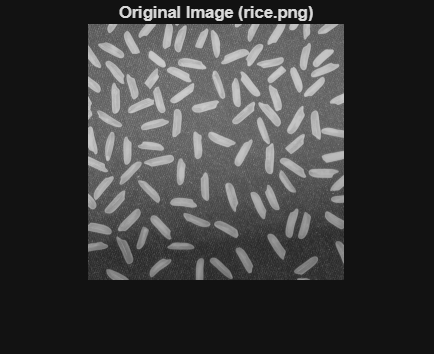

% Display the image in a figure
figure;
    imshow(img);
    title('Original Image (rice.png)');

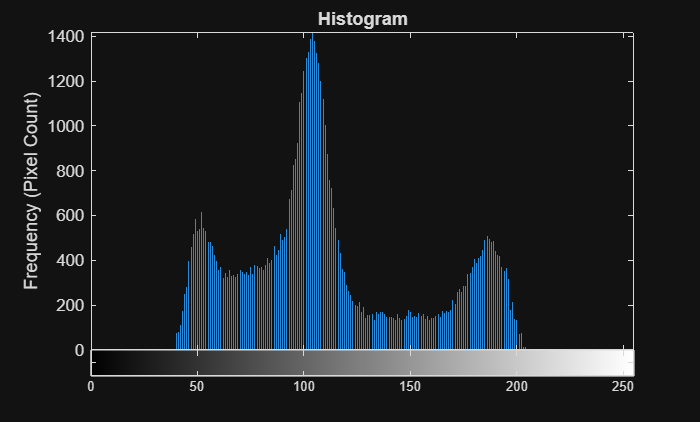

% Display the histogram
figure
    imhist(img);
    ylabel('Frequency (Pixel Count)');
    title('Histogram');
    axis tight;

### **1.2 Grayscale (2D) vs. Color (3D) Images**

The `rice.png` image is **grayscale**. Its size is 2D (Rows x Columns). Color images (like JPEG or standard PNGs) are **3D**. They have a 3rd dimension for the Red, Green, and Blue color channels. 

Let's load a built-in color image to see this.

% 1. Load a built-in COLOR image
I_color = imread('peppers.png');

figure;
    subplot(2, 2, 1);
        imshow(I_color);
        title('Original Color Image');

% 2. Check the size: It will be [Height, Width, 3]
disp('Size of Color Image (M x N x 3):');

Size of Color Image (M x N x 3):


size(I_color)

ans =    384   512     3


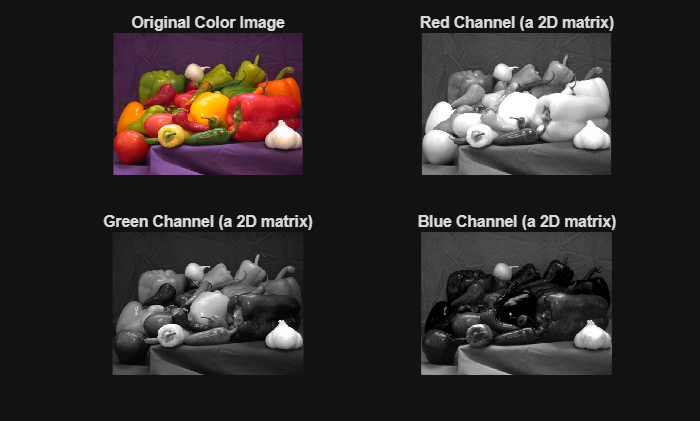


% 3. We can "slice" the 3D matrix to get each channel
I_red   = I_color(:,:,1); % Red Channel
I_green = I_color(:,:,2); % Green Channel
I_blue  = I_color(:,:,3); % Blue Channel
    subplot(2, 2, 2);
        imshow(I_red);
        title('Red Channel (a 2D matrix)');

    subplot(2, 2, 3);
        imshow(I_green);
        title('Green Channel (a 2D matrix)');

    subplot(2, 2, 4);
        imshow(I_blue);
        title('Blue Channel (a 2D matrix)')

**Converting Color to Grayscale**

Most analysis (like thresholding) is done on grayscale images. We use `rgb2gray` to convert the 3D color matrix into a 2D grayscale matrix. 

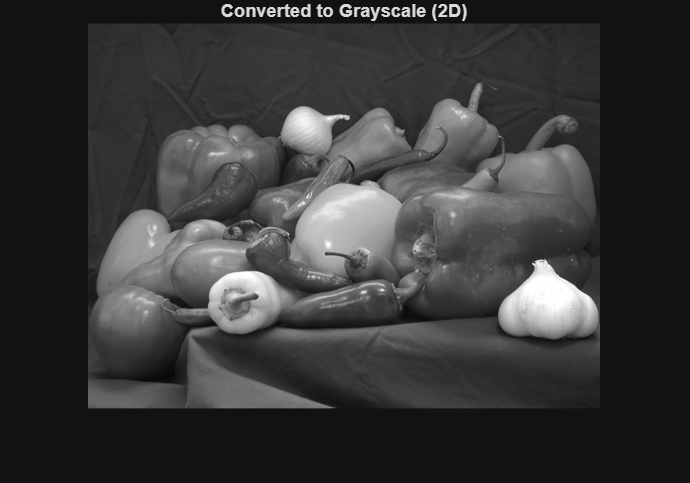

I_gray = rgb2gray(I_color);

figure;
    imshow(I_gray);
    title('Converted to Grayscale (2D)');


disp('Size of Grayscale Image (M x N):');

Size of Grayscale Image (M x N):


size(I_gray)        

ans =    384   512


### **1.3 Get Image Statistics (Explaining the Histogram)**

Let's get the descriptive statistics for our image "matrix." Notice how these numbers match the histogram:

- **Min/Max intensity** shows the range of the x-axis.

- The **Mean intensity** is the "average" brightness. We can see two distinct "humps" on the histogram: a large, dark one for the background and a smaller, lighter one for the rice grains.

disp('--- Image Statistics ---');

--- Image Statistics ---



% Get the dimensions (Height x Width)
[height, width] = size(img);
fprintf('Size: %d rows × %d columns\n', height, width);

Size: 256 rows × 256 columns



% Get the data type (e.g., uint8)
fprintf('Data type: %s\n', class(img));

Data type: uint8



% Get the intensity range
fprintf('Min intensity: %d\n', min(img(:)));

Min intensity: 40


fprintf('Max intensity: %d\n', max(img(:)));

Max intensity: 204



% Get the mean (average) intensity
fprintf('Mean intensity: %.2f\n', mean(img(:)));

Mean intensity: 111.25


disp('--------------------------');   

--------------------------


### **1.4 Accessing and Modifying Pixels**

Since the image `img` is just a matrix, we can access any pixel by using its (row, column) coordinates. Remember, the origin (1, 1) is at the **top-left corner**.

Let's read the value of a single pixel and then set a whole region of the image to black (an intensity value of 0).

% --- Accessing a Pixel ---
% Get the intensity value at row 100, column 150
pixel_value = img(100, 150);
fprintf('The pixel value at (100, 150) is: %d\n', pixel_value);

The pixel value at (100, 150) is: 177


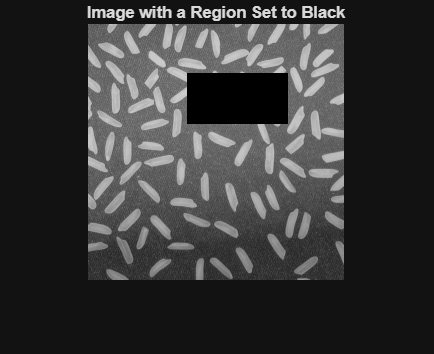

% --- Modifying a Region ---
% Create a copy of the image to modify
img_modified = img;

% Set a 50x100 pixel box to black (value = 0)
% Starting at row 50, column 100
img_modified(50:100, 100:200) = 0; % [rows, columns]

figure;
imshow(img_modified);
title('Image with a Region Set to Black');

### 1.5 A Warning About Data Types (`uint8` vs. `double`)

Before we do math, we must understand data types.

- `imread` loads images as `uint8` (unsigned 8-bit integer).

- This means values are whole numbers from **0 to 255**. 

- If you do `200 + 100`, the answer is **255** (it "clips"), not 300.

For correct math, we should first convert the image to `double` (a data type that can have decimals and go beyond 255).

- The standard way is to use `im2double()`, which converts the 0-255 range to a **0.0 to 1.0** range. 

- We do our math, and then convert back using `im2uint8()`.

### **1.6 Image Math (Brightness Adjustment)**

We can perform math on the entire matrix at once. To make the image brighter, we will use the correct method:

- Convert the image to `double` (range [0, 1]).

- Add our brightness value (e.g., 0.3 for 30%).

- Convert back to `uint8` (range [0, 255]) for display.

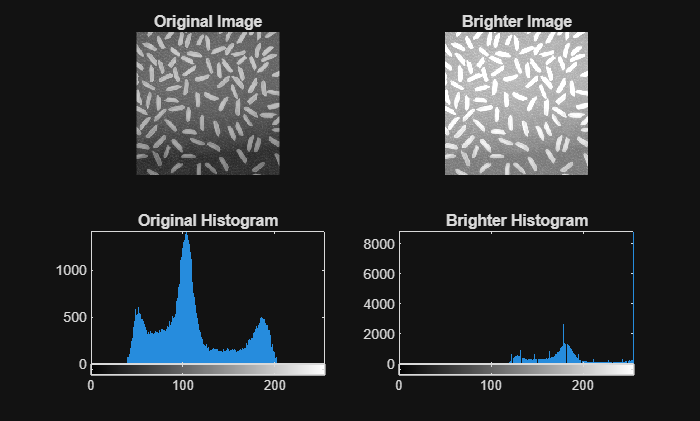

% Use the original grayscale image
img = imread(which('rice.png'));

% 1. Convert to double (range 0.0 to 1.0)
img_double = im2double(img);

% 2. Add 0.3 (30% brightness)
img_brighter_double = img_double + 0.3;

% 3. Convert back to uint8 (range 0-255) for display.
%    im2uint8 automatically handles clipping values > 1.0.
img_brighter_uint8 = im2uint8(img_brighter_double);

% --- Display Results ---
figure;
    subplot(2, 2, 1);
        imshow(img);
        title('Original Image');

    subplot(2, 2, 2);
        imshow(img_brighter_uint8);
        title('Brighter Image');

    subplot(2, 2, 3);
        imhist(img);
        title('Original Histogram');
        axis tight;

    subplot(2, 2, 4);
        imhist(img_brighter_uint8);
        title('Brighter Histogram');
        axis tight;

**Observation:** Notice how the entire histogram has shifted to the right. All the values are now "bunched up" at 255 (pure white) because we clipped them.

### **1.7 Image Math (Image Negation)**

To create a "negative" of the image, we do the same process. The "negative" of an image in the [0, 1] range is `1.0 - value`.

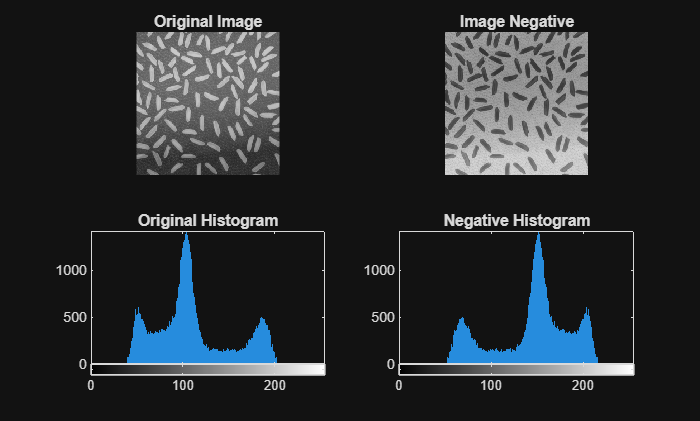

% 1. We already have img_double from the previous step
%    (If running this section alone, uncomment the next two lines)
% img = imread(which('rice.png'));
% img_double = im2double(img);

% 2. Subtract every pixel value from 1.0
img_negative_double = 1.0 - img_double;

% 3. Convert back to uint8
img_negative_uint8 = im2uint8(img_negative_double);

% --- Display Results ---
figure;
    subplot(2, 2, 1);
        imshow(img);
        title('Original Image');

    subplot(2, 2, 2);
        imshow(img_negative_uint8);
        title('Image Negative');

    subplot(2, 2, 3);
        imhist(img);
        title('Original Histogram');
        axis tight;

    subplot(2, 2, 4);
        imhist(img_negative_uint8);
        title('Negative Histogram');
        axis tight;

**Observation:** As you can see, the histogram is now flipped horizontally. The dark background (low values) became a light background (high values).

## Part 2: What is Segmentation?

Segmentation is the act of separating our image into regions (e.g., "rice" vs. "background"). The simplest way is **thresholding**. We will pick a value in the "valley" between the two humps on the histogram.

Our goal in segmentation is to create a **binary mask**. This is a logical matrix where:

- `1` (true), shown as **white**, represents the pixels we *care about* (our "Region of Interest," or ROI).

- `0` (false), shown as **black**, represents the background.

We will use this mask to "mask out" the background, allowing us to analyze *only* the objects of interest (the rice grains).

### **2.1 Manual Thresholding**

Based on the histogram, the valley is around 100-120. Let's try a manual threshold value of `100`.

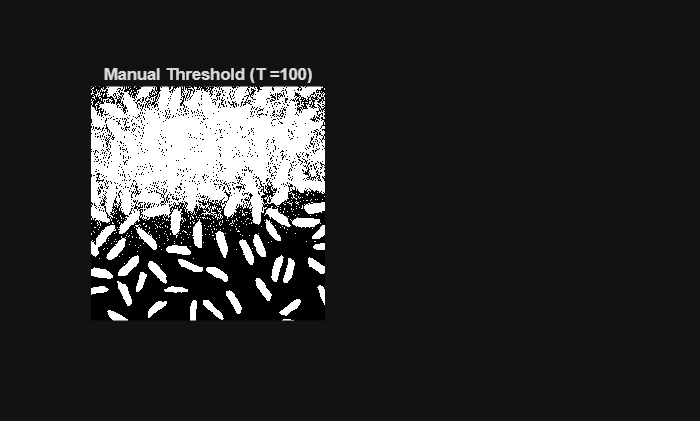

% Set a manual threshold
T_manual = 100;

% Any pixel > 100 becomes 1 (white)
% Any pixel <= 100 becomes 0 (black)

BW_manual = img > T_manual;

figure;
    subplot(1, 2, 1);
    imshow(BW_manual);
    title(['Manual Threshold (T =', num2str(T_manual), ')']);

### **2.2 Automatic Thresholding (Otsu's Method)**

This is good, but we had to *guess* the value `100`. This is **subjective**. If our next photo has different lighting, our `100` value might fail completely.

A more robust, **objective** method is to have the computer analyze the histogram and find the optimal value for us.

We use `graythresh` (which uses "Otsu's Method") to find the best value in the "valley" between the two histogram humps.

% 1. Find the optimal threshold (value is from 0 to 1)
T_auto_normalized = graythresh(img);
fprintf('Otsu Threshold (0-1): %.3f\n', T_auto_normalized);

Otsu Threshold (0-1): 0.514



% Convert it back to the 0-255 scale
T_auto = T_auto_normalized * 255;
fprintf('Otsu Threshold (0-255): %.1f\n', T_auto);

Otsu Threshold (0-255): 131.0


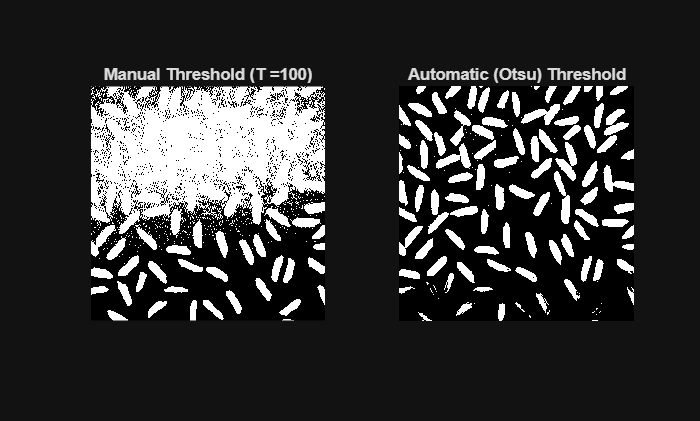


% 2. Apply this threshold using the 'imbinarize' function
BW_auto = imbinarize(img, T_auto_normalized);

% 3. Display the result
subplot(1, 2, 2);
imshow(BW_auto);
title('Automatic (Otsu) Threshold');

### **2.3 The Problem: Our Mask Isn't Clean!**

Look closely at the `BW_auto` image from the last step. If you zoom in, you will see it's "noisy."

- There are small white specks in the black background (this is "salt-and-pepper" noise).

- Some rice grains have small black holes inside them.

If we tried to count the rice grains *now*, our program would give a wrong answer. It would count all the tiny noise specks as "rice."

**This is the key takeaway:** Simple thresholding is a good *first step*, but it's not a complete solution. Our mask is not yet clean enough for analysis.

**Next week,** we will learn how to use **Filtering** and **Morphological Operations** (`imopen`, `imclose`) to remove this noise, fill the holes, and create a perfectly clean mask.